**Task 1 a)**

clc;
clear;
close all;
x = [2 2 4 5];
y = [4 5 4 0];
[r,k] = xcorr(x,y);

disp(r);
disp(k);
% range of k: -3 <= k <= 3

**Task 1 b)**

n1 + n2 -1

**Task 1 c)**

clc;
clear;
close all;
x = [2 2 4 5];
y = [4 5 4 0];
samples = 1:length(x);
[r,k] = xcorr(x,y);

subplot 311;
stem(samples,x);
title("x[t]");
xlabel("samples");
ylabel("Amplitude");

subplot 312;
stem(samples,y);
title("y[t]");
xlabel("samples");
ylabel("Amplitude");

subplot 313;
stem(k,r);
title("r[k]");
xlabel("k");
ylabel("r");

**Task 1 d)**

As the shift increases from -3, the correlation also rises, reaching its peak at 1. After that, it starts to decrease, indicating growing dissimilarity.

**Task 2**

clc;
clear;
close all;
x = [3 4 5 8];
samples = 1:length(x);
[r,k] = xcorr(x);

subplot 211;
stem(samples,x);
title("x[t]");
xlabel("samples");
ylabel("Amplitude");

subplot 212;
stem(k,r);
title("r[k]");
xlabel("k");
ylabel("r");

Since the signal is compared with itself, the highest similarity occurs at 0, where there is no shift. As the shift increases or decreases, the correlation gradually decreases, showing reduced similarity.

**Task 3**

clc;
clear;
close all;
[y , Fs_y] = audioread('audios/task3/speech_segment.wav'); % segment of signal we want to
%search
[x , Fs_x] = audioread('audios/task3/speech.wav'); % complete signal or speech
%sound(y, Fs_y) % sends the signal in vector y (with sample frequency Fs_y)
%to the speaker on PC
%pause(2) %to insert a pause of 2 seconds between the two audio files
%sound(x, Fs_x)

[correlation , lag1] = xcorr(x,y); % Correlation is obtained
[cmax, idx] = max(abs(correlation)); % Finding maximum value
Nonlinear_Effect = (1.1* correlation/cmax).^3;

figure;

subplot 311;
plot(x);
title("x(n)");

subplot 312;
plot(y);
title("y(n)");

subplot 313;
plot(lag1,Nonlinear_Effect);
title("corelation output");
location=lag1(idx);
sound(x(location:end),Fs_x);

Without normalization, the correlation output would have large amplitude values, making it harder to identify the peak. By normalizing, the values range between -1 and 1, making the peak more visible. Using correlation, we extract the common audio segment, and the peak shows where the match is strongest. The index of this peak helps locate and play the matching audio from that point onward.

**Task 4**

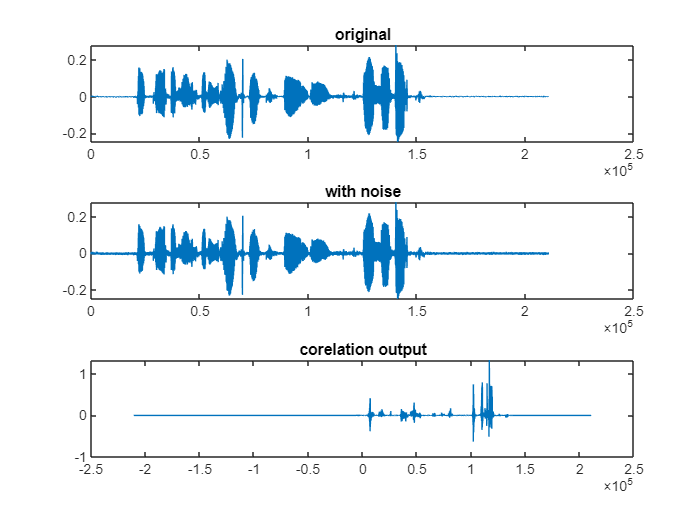

clc;
clear;
close all;
[x , Fs_x] = audioread('audios/task3/speech.wav');
[y , Fs_y] = audioread('audios/task3/speech_segment.wav');
x_noise = 0.2 * randn(size(x));
x_new = x + x_noise / 100;


[correlation , lag1] = xcorr(x_new, y); % Correlation is obtained
[cmax, idx] = max(abs(correlation)); % Finding maximum value
Nonlinear_Effect = (1.1* correlation/cmax).^3;
location= lag1(idx);
sound(x_new(location:end),Fs_x);

figure;

subplot 311;
plot(x);
title("original");

subplot 312;
plot(x_new);
title("with noise");

subplot 313;
plot(lag1,Nonlinear_Effect);
title("corelation output");

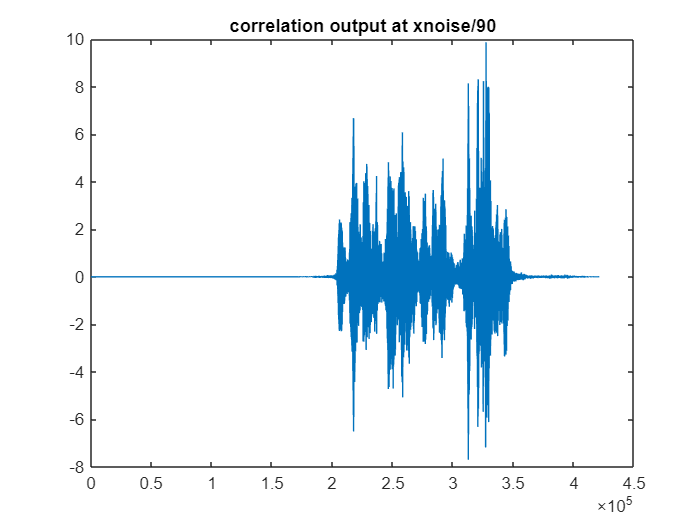

xnew1 = x+ x_noise / 90; 
Px = (sum(x.^2))/length(x);

Pn = (sum((x_noise / 90) .^ 2)) / length(x);
snr = Px / Pn;
[correlation, lag1] = xcorr(xnew1,y);

figure;
plot(correlation);
title("correlation output at xnoise/90");

**Task 5)**

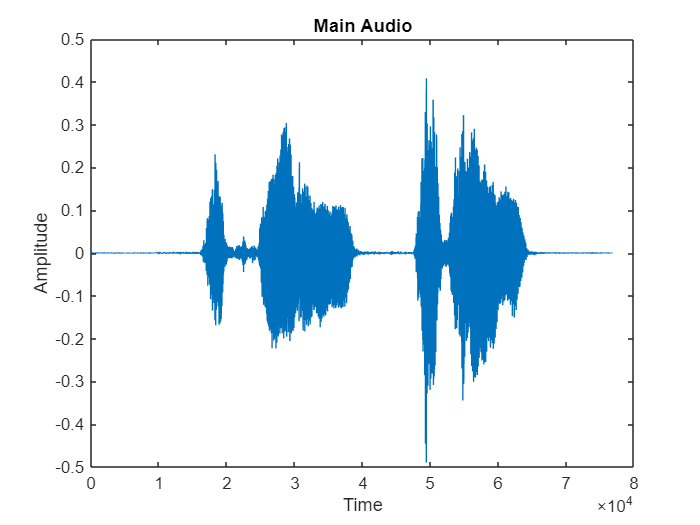

clc;
clear;
close all;
audio_loc = "audios/task5/";

[main_audio, Fs_m] = audioread(audio_loc + "main_audio.wav");
figure;
plot(main_audio);
title("Main Audio")
xlabel("Time")
ylabel("Amplitude")


[okay1, Fs1]= audioread(audio_loc + "okay_1.wav");
[okay2, Fs2]= audioread(audio_loc + "okay_2.wav");
[okay3, Fs3]= audioread(audio_loc + "okay_3.wav");
[okay4, Fs4]= audioread(audio_loc + "okay_4.wav");
sound(okay3);

[correlation1, lag1] = xcorr(okay1, main_audio);
[correlation2, lag2] = xcorr(okay2, main_audio);
[correlation3, lag3] = xcorr(okay3, main_audio);
[correlation4, lag4] = xcorr(okay4, main_audio);


cmax1= max(abs(correlation1));
cmax2= max(abs(correlation2));
cmax3= max(abs(correlation3));
cmax4= max(abs(correlation4));
cmax_list = [cmax1 cmax2 cmax3 cmax4]

cmax_list =    13.1294   13.2471    9.8803    2.3188


threshold=13;

for i = 1:4
    if (cmax_list(i) > threshold)
        fprintf('Password detected for okay_%d.wav\n', i);
    else 
        fprintf('Password not detected for okay_%d.wav\n', i); 
    end 
end

Password detected for okay_1.wav
Password detected for okay_2.wav
Password detected for okay_3.wav


Password not detected for okay_4.wav


Chose 13 as the threshold because the other audios were not close to the original phrase. This isn't a reliable password detector because it fails to recognize the last two audios due to differences in accents or speaking styles, even though the words were the same. Since it can't handle these variations, it's not effective.